Importing Covid'19 from JHU CSSEIG.

confirmed = loadData('confirmed')

confirmed = 266×184 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36

deaths = loadData('deaths')

deaths = 266×184 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36   

recovered = loadData('recovered')

recovered = 253×184 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36


region = 12; % Queensland
t = 12:width(confirmed) 

t =     12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61


qlpop = 5072000; 

s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t};
i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t};
r1 = deaths{region,t} + recovered{region,t};

[, v] = betaVegaCalc((confirmed{region,t}), (deaths{region,t}), (recovered{region,t}), 80, 30);

Graphing the S, I, R population.

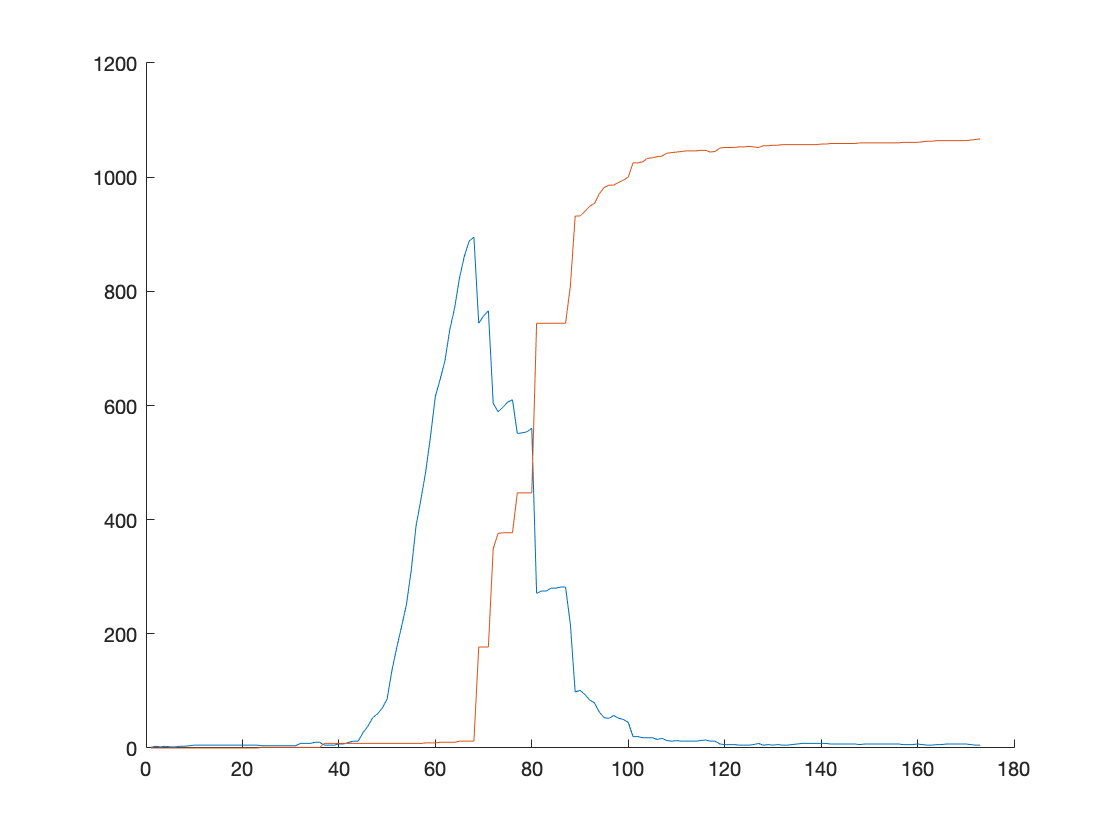

figure
hold on
%plot(5072000-confirmed{region,t}-deaths{region,t}-recovered{region,t})
plot(confirmed{region,t}-deaths{region,t}-recovered{region,t})
plot(deaths{region,t}+recovered{region,t})

[pks, locs] = findpeaks(confirmed{region,t}-deaths{region,t}-recovered{region,t})

pks =      3     3     5    10   895   766   610   560   282   101    57    17    13    14     8     6     6     8     7     7     7


locs =      2     4    10    35    68    71    76    80    86    90    97   107   110   116   127   129   131   136   149   160   166


The Jacobian matrix is used to calculate the changes in 

br = 0;

u = 1 - v;
t=20;

s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t}

s1 = 5071996

i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t}

i1 = 4

r1 = deaths{region,t} + recovered{region,t}

r1 = 0

J = [-b(t)*i1-u(t) -b(t)*s1 0; b(t)*i1 b(t)*s1-v(t)-u(t) 0; 0 v(t) -u(t)];
J

J =    -1.0000   -5.0000         0
    0.0000    4.0000         0
         0         0   -1.0000


[V,D] = eig(J)

V =    -1.0000    0.7071         0
    0.0000   -0.7071         0
         0         0    1.0000


D =    -1.0000         0         0
         0    4.0000         0
         0         0   -1.0000


qlpop = 5072000
d1 = 12
s1 = qlpop - confirmed{12,12} - deaths{12,12} - recovered{12,12}
i1 = confirmed{12,12} - deaths{12,12} - recovered{12,12}
r1 = deaths{12,12} + recovered{12,12}
g1 = [s1 i1 r1]
d2 = 50
s2 = qlpop - confirmed{12,d2} - deaths{12,d2} - recovered{12,d2}
i2 = confirmed{12,d2} - deaths{12,d2} - recovered{12,d2}
r2 = deaths{12,d2} + recovered{12,d2}
g2 = [s2 i2 r2]
M = [s2/s1 (s2-s1)/s1 0; 0 (i2-r2)/i2 (r2-r1)/r2; 0 0 1]